# Simulink Control Loop

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_02_21_ControlLoop/ControlLoop.prj)

This week I received a series of interesting questions on the basics of putting together a simulation of a control loop involving a Simscape continuous plant and a discrete controller. The questions are summarized in this image:

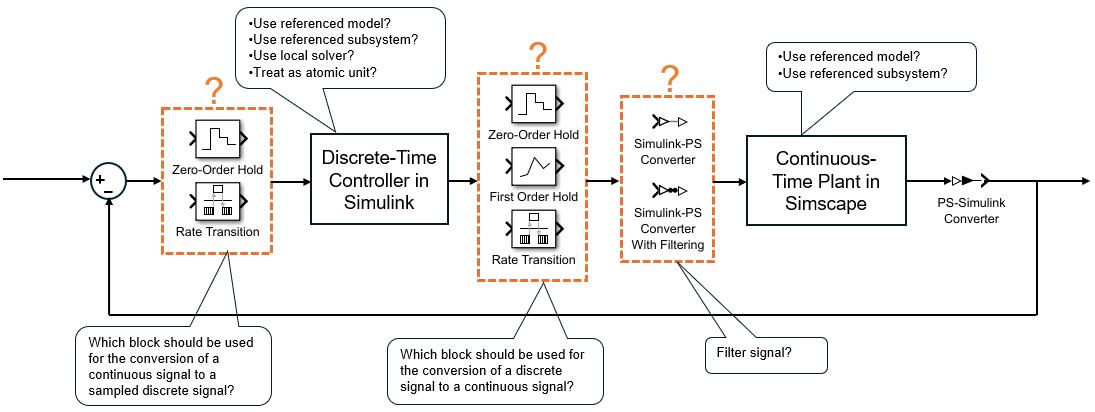

Here are my answers to those questions.

## Discrete Controller

I recommend implementing the controller in a separate model file and bringing it in the simulation using the [model block](https://www.mathworks.com/help/simulink/slref/model.html). The main reason is that you will likely want to generate code using [Simulink Coder](https://www.mathworks.com/products/simulink-coder.html) or [Embedded Coder](https://www.mathworks.com/products/embedded-coder.html) for the controller at some point. With [model reference](https://www.mathworks.com/help/simulink/model-reference.html), the controller is a standalone atomic unit and you can define a strong interface to it. This ensures that the controller behaves identically as part of the closed-loop simulation and when you will generate code for it.

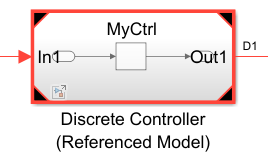

## Continuous Plant

Here, I would say: *It depends...*

One important aspect to consider is algebraic loops. In this kind of closed-loop simulations, it's typically the plant that breaks potential algebraic loops. If the plant is an atomic unit, there are more chances to run into [artificial algebraic loops](https://www.mathworks.com/help/releases/R2024b/simulink/ug/algebraic-loops.html#buqn11q).

Here is how I typically decide:

- **Subsystem Reference:** This is usually my first choice. It's the simplest way to save the content of a subsystem to a separate file and avoid merge conflicts. Leaving the subsystem NOT atomic will ensure that no [artificial algebraic loops](https://www.mathworks.com/help/releases/R2024b/simulink/ug/algebraic-loops.html#buqn11q) get introduced. 

- **Model Reference:** I consider using model referencing if the time it takes to initialize the simulation is a concern. If the plant becomes complex and you are not actively modifying it, I recommend setting the model block in Accelerator mode. That way, the referenced model will be accelerated once and the artifacts stored in a [cache file](https://www.mathworks.com/help/simulink/ug/reuse-simulation-builds-for-faster-simulations.html) (If you have a CI system, you can even get the cache files built automatically overnight). That way, subsequent simulations will initialize almost instantly. If making the plant a referenced model introduces an artificial algebraic loop, try enabling the setting [Minimize artificial algebraic loop occurrences](https://www.mathworks.com/help/simulink/gui/minimizealgebraicloopoccurrences.html). With this option enabled, Simulink will do extra work to try avoiding artificial algebraic loops. If you need the performance gain of model reference but cannot avoid artificial algebraic loops, you will need to introduce delays somewhere in the loop.

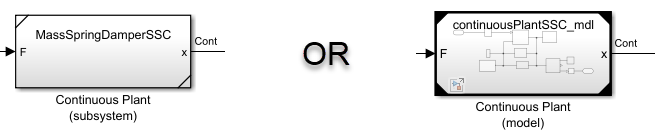

If the time spent during model initialization is a big deal for you, I recommend visiting those blog posts focused on this topic:

- [Speeding up Initialization for Accelerator Mode](https://blogs.mathworks.com/simulink/2015/06/12/speeding-up-initialization-for-accelerator-mode/)

- [Accelerator Cache and Rebuilds – Everything you need to know](https://blogs.mathworks.com/simulink/2023/10/18/accelerator-cache-and-rebuilds-everything-you-need-to-know/)

## Continuous to Discrete Conversion

Use Rate Transition blocks. Most likely, since the rate transition is from fast to slow, the Rate Transition will behave exactly like the Zero-Order Hold block. I recommend looking at the [Rate Transition documentation](https://www.mathworks.com/help/simulink/slref/ratetransition.html) to see the various options it offers.

## Discrete to Continuous Conversion

Here we have another case of *it depends...*

The main question you should ask yourself is: Does the quantization effect caused by the discrete rate impacts the plant results significantly?

[**First Order Hold**](https://www.mathworks.com/help/simulink/slref/firstorderhold.html)**:** Your best choice for performance. This block interpolates the input signal to generate a continuous output. This helps avoiding solver resets, which are known to slow down simulations. Here is a blog post where I explain the advantages of the First Order Hold block: [**A New First Order Hold!**](https://blogs.mathworks.com/simulink/2020/01/17/a-new-first-order-hold/?s_tid=srchtitle_site_search_1_Guy%2520first%20order%20hold). Another great advantage of the First Order Hold block: It can help breaking algebraic loops!

**Rate Transition:** Use this block if the interpolation introduced by the First Order Hold block impacts the results too significantly. 

Here is a simple example. 

open_system('testRamp')

Let's simulate this  model with two different discrete rates and compare the results of the Rate Transition and the First Order Hold block.

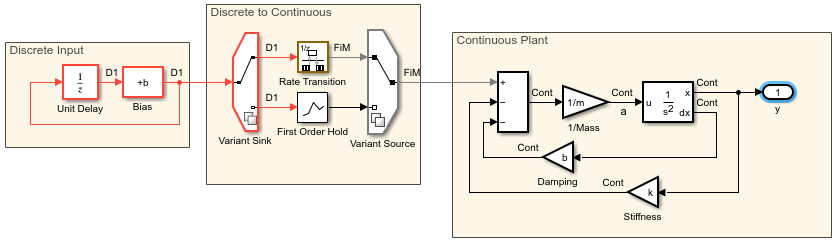

To simulate the model, I decided to use the new [Design Study](https://www.mathworks.com/help/releases/R2024b/simulink/slref/simulink.multisim.designstudy.html) feature released in R2024a:

% Create two variables
sampleTimeVar = simulink.multisim.Variable("sampleTime", [1e-4 1]);
d2cVar = simulink.multisim.Variable("d2c",  [1 2]);
% Create an exhaustive combination
exhaustive = simulink.multisim.Exhaustive([sampleTimeVar,  d2cVar]);
% Make it a study for my model
designStudy = simulink.multisim.DesignStudy("testRamp", exhaustive);
out = sim(designStudy,'ShowProgress','off');

Looking at the results, we can see that for the sample time of 1 second, the First Order Hold interpolation changes the results significantly while the impact for the sample time of 1e-4 second is negligible.

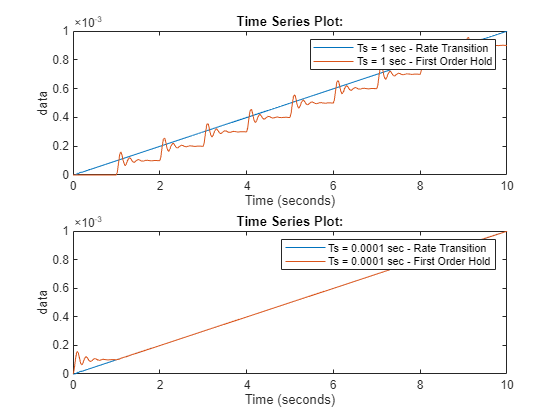

figure;
subplot(2,1,1)
plot(out(1).yout{1}.Values)
hold on
plot(out(2).yout{1}.Values)
legend({'Ts = 1 sec - Rate Transition','Ts = 1 sec - First Order Hold'});
subplot(2,1,2)
plot(out(3).yout{1}.Values)
hold on
plot(out(4).yout{1}.Values)

legend({'Ts = 0.0001 sec - Rate Transition','Ts = 0.0001 sec - First Order Hold'});

## Simulink - PS Converter Filtering

The [Simulink-PS Converter](https://www.mathworks.com/help/releases/R2024b/simscape/ref/simulinkpsconverter.html) block has an option to filter the incoming signal.

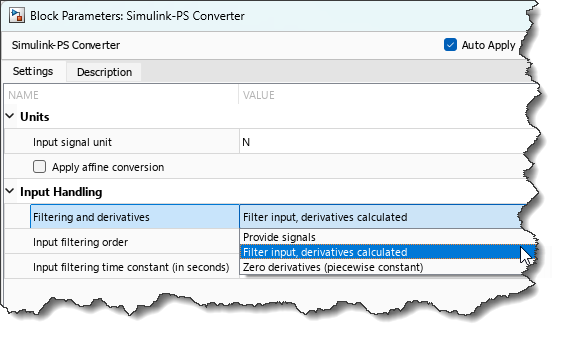

There are two reasons for this option:

- Most Simscape blocks work better when the input signal, and its first and second derivatives, are continuous.

- Some Simscape blocks need the derivative of the input signals to compute their results.

Filtering the input and computing the derivative of this filtered input is a simple way to ensure that those two requirements are met.

Based on that, my recommendation is to enable filtering if you get an error about missing derivatives, or if the signals you are feeding to Simscape have significant discontinuities. When enabling filtering, pick a time constant that is small enough to not impact the system dynamics significantly, but not too small to force Simulink solver to take very small steps and impact performance.

## Final Model

Here is a model implementing all of the above

open_system('exampleLoopSimscape');

The four black corners of the Discrete Controller indicate that this is a referenced model in accelerator mode. The two white corners on the Continuous Plant indicate that it is a Subsystem Reference.

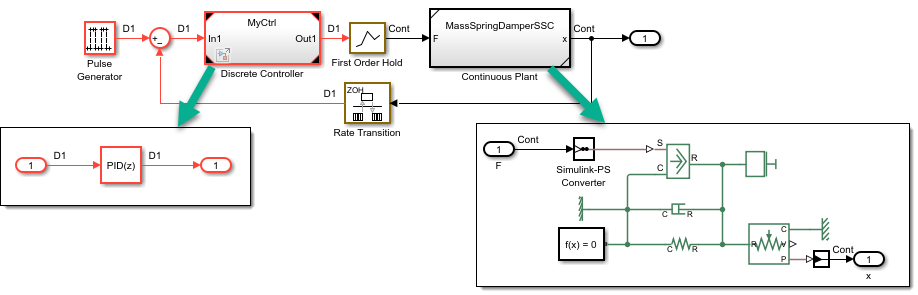

## Now it's your Turn

What are your best practices when putting together closed loop simulations? Let us know in the comments below.